# Inspired by Choi Iteration 00

clear

## Definitions

### Plunger

pl_d_out   =	17.5;	% mm
pl_d_hole  =	1;    % mm
pl_height  =	15.5;	    % mm
pl_d_in    =	12;	% mm
pl_A_out   =    pl_d_out^2/4*pi;    % mm^2
pl_A_hole  =    pl_d_hole^2/4*pi    % mm^2

pl_A_hole = 0.7854

pl_A_in    =    pl_d_in^2/4*pi;    % mm^2
pl_A_u     =    pl_A_out - pl_A_in;     % mm^2
pl_m       =    0.012;  % kg
pl_rom     =    0.003;  % m

## Pipes

ip_d = 50; % mm
ip_A = ip_d^2/4*pi; % mm^2
op_d = 25; % mm
op_A = op_d^2/4*pi; % mm^2
V_psu       =   ip_A*250; % mm^3
V_psd       =   op_A*250; % mm^3

io_d = 10; % mm
io_A = io_d^2/4*pi; % mm^2
oo_d = 10; % mm
oo_A = oo_d^2/4*pi; % mm^2

### Outlet

o_d_out	=   17.83;	    % mm
o_d_in	=   10;	% mm
A_adj = 0.5^2/4*pi;%o_d_out^2/4*pi - pl_A_out % mm^2
oe_o_d = 3; % mm
oe_o_A = oe_o_d^2/4*pi; % % mm^2

### Pintle Groove

pg_d	    =   13.035;	% mm
PG_depth	=   30.2;	% mm

### Pintle

pi_height	=   29.4;	% mm
pi_d_out	=   12.84;	% mm
pi_d_in	    =   16.022;	% mm

### Volume

v_closed	=   1722;	% mm^3
v_open	    =   1037;	% mm^3

## Init arrays

dt = 0.000001; % s
T = 0.02/dt; % s
% t = zeros(T); % s
% P_cr = zeros(T); % bar
% T_cr = zeros(T); % K
% P_u = zeros(T); % bar
% T_u = zeros(T); % K
% P_d = zeros(T); % bar
% T_d = zeros(T); % K
% P_psu = zeros(T); % K
% T_psu = zeros(T); % K
% P_psd = zeros(T); % K
% T_psd = zeros(T); % K
% 
% x = zeros(T); % m
% v = zeros(T); % m/s
% a = zeros(T); % m/s^2
% 
% V_cr = zeros(T); % mm^3
% 
% pilot = zeros(T); % 1 = open, 0 = closed
% 
% A_m = zeros(T); % mm^2
% 
% m_dot_u_psu = zeros(T); % kg/s
% m_dot_psu_cr = zeros(T); % kg/s
% m_dot_cr_psd = zeros(T); % kg/s
% m_dot_psu_psd = zeros(T); % kg/s
% m_dot_psd_d = zeros(T); % kg/s
% 
% m_dot_cr_net = zeros(T); % kg/s
% m_dot_psu_net = zeros(T); % kg/s
% m_dot_psd_net = zeros(T); % kg/s
% 
% F_cr = zeros(T); % N
% F_d = zeros(T); % N
% F_u = zeros(T); % N
% F_f = zeros(T); % N
% F_s = zeros(T); % N
% F = zeros(T); % N
% 
% m_cr = zeros(T);
% m_psu = zeros(T);
% m_psd = zeros(T);

## Test Case 1

- Infinite Upstream Volume @ 400 bar 273 K

- Pipe Section after upstream @ 1 bar 273 K

- Infinite Downstream Volume @ 1 bar 273 K

- Pipe Section before downstream @ 1 bar 273 K

- Outlet external orifice D = 2 mm

- Pilot closed @ t(0)

- P_cr = 0 bar @ t(0)

- Plunger displacement x = 0 @ t(0)

gam = 1.4;
R = 296.8; % kJ/kgK
polythropic_index = gam ;

damper = 1000; % kg/s

t(1) = 0; % s
P_cr(1) = 400; % bar
T_cr(1) = 273; % K
P_u(1) = 400; % bar
T_u(1) = 273; % K
P_d(1) = 1; % bar
T_d(1) = 273; % K
P_psu(1) = 400; % K
T_psu(1) = 273; % K
P_psd(1) = 1; % K
T_psd(1) = 273; % K

x(1) = 0; % m
v(1) = 0; % m/s
a(1) = 0; % m/s^2

V_cr(1) = v_closed; % mm^3

pilot(1) = 0; % 1 = open, 0 = closed

A_m(1) = o_d_in * pi * x(1) * 10^-3; % mm^2

m_dot_u_psu(1) = 0; % kg/s
m_dot_psu_cr(1) = 0; % kg/s
m_dot_cr_psd(1) = 0; % kg/s
m_dot_psu_psd(1) = 0; % kg/s
m_dot_psd_d(1) = 0; % kg/s

m_dot_cr_net(1) = 0; % kg/s
m_dot_psu_net(1) = 0; % kg/s
m_dot_psd_net(1) = 0; % kg/s

F_cr(1) = B_to_Pa(P_cr(1)) * pl_A_out * 10^-6; % N
F_d(1) = B_to_Pa(P_psd(1)) * pl_A_in * 10^-6; % N
F_u(1) = B_to_Pa(P_psu(1)) * pl_A_u * 10^-6; % N
F_f(1) = - damper * v(1); % N
F_s(1) = 50; % N
F(1) = - F_cr(1) + F_d(1) + F_u(1) + F_f(1) - F_s(1); % N

m_cr(1) = 0.014 * B_to_Pa(P_cr(1)) * v_closed * 10^-9 / (T_cr(1) * R);
m_psu(1) = 0.014 * B_to_Pa(P_psu(1)) * V_psu * 10^-9 / (T_psu(1) * R);
m_psd(1) = 0.014 * B_to_Pa(P_psd(1)) * V_psd * 10^-9 / (T_psd(1) * R);

for i = 2:(T-1)
    t(i) = t(i-1) + dt; % s
    pilot(i) = i < (0.5*T); % 1 = open, 0 = closed
    
    P_u(i) = P_u(i-1); % bar
    T_u(i) = T_u(i-1); % K
    P_d(i) = P_d(i-1); % bar
    T_d(i) = T_d(i-1); % K
    
    % Calculate forces
    F_cr(i) = B_to_Pa(P_cr(i-1)) * pl_A_out * 10^-6; % N
    F_d(i) = B_to_Pa(P_psd(i-1)) * pl_A_in * 10^-6; % N
    F_u(i) = B_to_Pa(P_psu(i-1)) * pl_A_u * 10^-6; % N
    F_f(i) = - damper * v(i-1); % N
    F_s(i) = F_s(1); % N
    F(i) = - F_cr(i) + F_d(i) + F_u(i) + F_f(i) - F_s(i); % N
    
    % Calculate displacement from previous forces
    x(i) = x(i-1) + v(i-1)*dt + 0.5*a(i-1)*dt^2; % m
    v(i) = v(i-1) + a(i-1)*dt; % m/s
    a(i) = F(i) / pl_m; % m/s^2
    if x(i) < 0
        x(i) = 0; % m
        v(i) = 0; % m/s
        a(i) = 0; % m/s^2
    elseif x(i) > pl_rom
        x(i) = pl_rom; % m
        v(i) = 0; % m/s
        a(i) = 0; % m/s^2
    end
    
    % Calculate Main area with new displacement
    A_m(i) = o_d_in * pi * x(i) * 10^-3; % m^2
    
    % Calculate Critical volume after displacement
    V_cr(i) = (pl_rom - x(i)) * (v_closed - v_open) / pl_rom + v_open; % mm^3
    
    % Isentropic Compression
    P_cr(i) = P_cr(i-1) * (V_cr(i-1)/V_cr(i))^polythropic_index; % Bar
    T_cr(i) = T_cr(i-1) * (P_cr(i)/P_cr(i-1))^(1-1/polythropic_index); % K
    
    % Critical volume / Actuation Chamber related
    m_dot_psu_cr(i) = mdot_orifice(...
        P_psu(i-1),P_cr(i) ,polythropic_index,A_adj    *10^-6,T_psu(i-1),R); % kg/s
    m_dot_cr_psd(i) = mdot_orifice(...
        P_cr(i), P_psd(i-1),polythropic_index,pl_A_hole*10^-6,T_cr(i), R) * (pilot(i)==1); % kg/s
    
    [P_cr(i), T_cr(i), m_cr(i)] = tank_discharge_P_io(P_cr(i),T_cr(i),m_cr(i-1),...
         [T_psu(i-1),       T_cr(i-1)],...
         [m_dot_psu_cr(i),  - m_dot_cr_psd(i)] * dt,...
         polythropic_index); % bar, K
    
    m_dot_cr_net(i) = m_cr(i) - m_cr(i-1); % kg/s
    
    % Pipe Section Upstream related
    m_dot_psu_psd(i) = mdot_orifice(P_psu(i-1),P_psd(i-1),polythropic_index,A_m(i),T_psu(i-1),R); % kg/s
    m_dot_u_psu(i) = mdot_orifice(P_u(i-1),  P_psu(i-1),polythropic_index,io_A    *10^-6,T_u(i-1),R); % kg/s
    
    [P_psu(i), T_psu(i), m_psu(i)] = tank_discharge_P_io(P_psu(i-1),T_psu(i-1),m_psu(i-1),...
         [T_u(i-1),        T_psu(i-1),          T_psu(i-1)],...
         [m_dot_u_psu(i),  - m_dot_psu_cr(i),   - m_dot_psu_psd(i)] * dt,...
         polythropic_index); % bar, K
    
    m_dot_psu_net(i) = m_psu(i) - m_psu(i-1); % kg/s
    
    % Pipe Section Upstream related
    m_dot_psd_d(i) = mdot_orifice(P_psd(i-1),P_d(i-1)  ,polythropic_index,oe_o_A    *10^-6,T_psd(i-1),R); % kg/s
    m_dot_psd_net(i) = m_dot_cr_psd(i) - m_dot_psd_d(i) + m_dot_psu_psd(i); % kg/s
    m_psd(i) = m_psd(i-1) + m_dot_psd_net(i) * dt; % kg
    [P_psd(i), T_psd(i)] = tank_discharge_P(P_psd(i-1),T_psd(i-1),m_psd(i-1),...
         - m_dot_psd_net(i) * dt,polythropic_index); % bar, K
    
    [P_psd(i), T_psd(i), m_psd(i)] = tank_discharge_P_io(P_psd(i-1),T_psd(i-1),m_psd(i-1),...
         [T_psd(i-1),        T_cr(i-1),         T_psu(i-1)],...
         [-m_dot_psd_d(i), m_dot_cr_psd(i),   m_dot_psu_psd(i)] * dt,...
         polythropic_index); % bar, K
    
    m_dot_psd_net(i) = m_psd(i) - m_psd(i-1); % kg/s
end


## Results

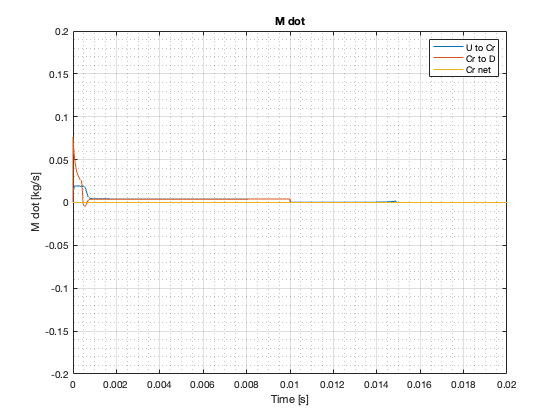

figure(1)
plot(t,m_dot_psu_cr,t,m_dot_cr_psd,t,m_dot_cr_net)
grid on, grid minor, xlabel('Time [s]'), ylabel('M dot [kg/s]'), title('M dot')
legend('U to Cr', 'Cr to D', 'Cr net'),ylim([-0.2 0.2])

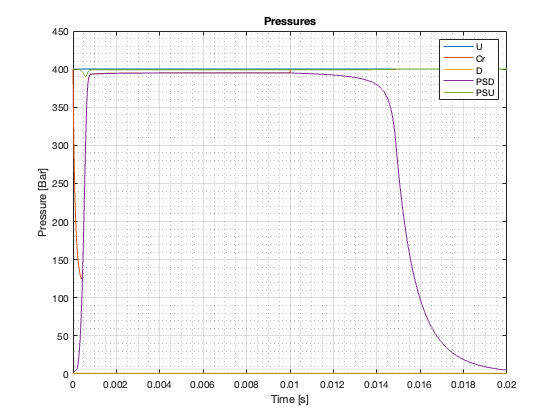

figure(2)
plot(t,P_u,t,P_cr,t,P_d,t,P_psd,t,P_psu)
grid on, grid minor, xlabel('Time [s]'), ylabel('Pressure [Bar]'), title('Pressures')
legend('U','Cr','D','PSD','PSU'),ylim([0 450])

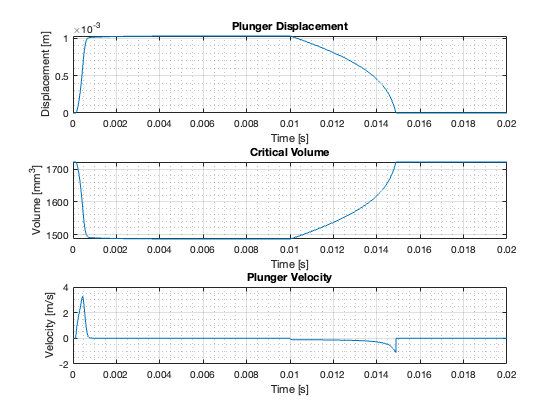

figure(3)
subplot(3,1,1)
plot(t,x)
grid on, grid minor, xlabel('Time [s]'), ylabel('Displacement [m]'), title('Plunger Displacement')
subplot(3,1,2)
plot(t,V_cr)
grid on, grid minor, xlabel('Time [s]'), ylabel('Volume [mm^3]'), title('Critical Volume')
subplot(3,1,3)
plot(t,v)
grid on, grid minor, xlabel('Time [s]'), ylabel('Velocity [m/s]'), title('Plunger Velocity')

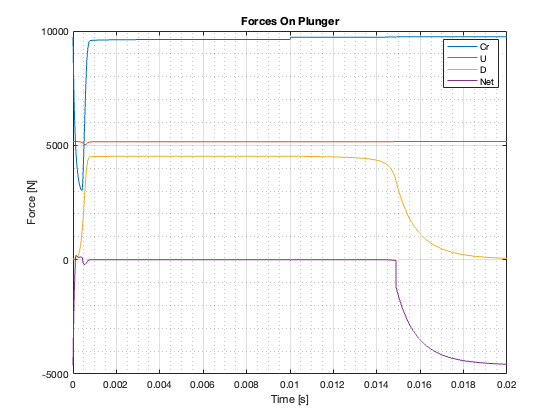

figure(4)
plot(t,F_cr,t,F_u,t,F_d,t,F)
grid on, grid minor, xlabel('Time [s]'), ylabel('Force [N]'), title('Forces On Plunger')
legend('Cr','U','D','Net')%,ylim([-20000 20000])

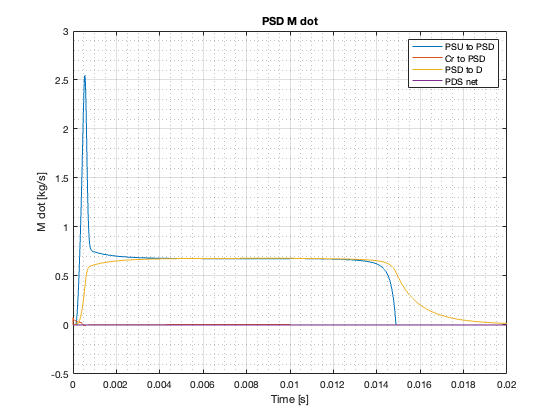

figure(5)
plot(t,m_dot_psu_psd,t,m_dot_cr_psd,t,m_dot_psd_d,t,m_dot_psd_net)
grid on, grid minor, xlabel('Time [s]'), ylabel('M dot [kg/s]'), title('PSD M dot')
legend('PSU to PSD', 'Cr to PSD', 'PSD to D', 'PDS net')%,ylim([-0.2 0.2])

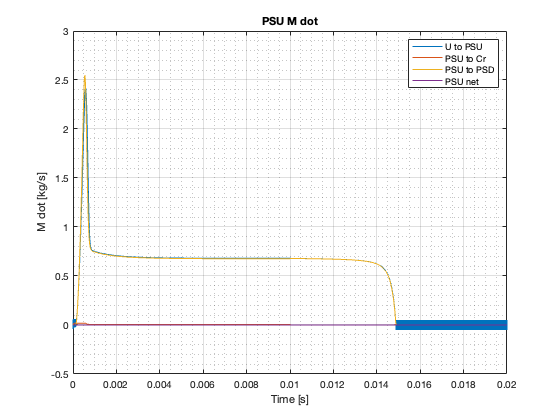

figure(6)
plot(t,m_dot_u_psu,t,m_dot_psu_cr,t,m_dot_psu_psd,t,m_dot_psu_net)
grid on, grid minor, xlabel('Time [s]'), ylabel('M dot [kg/s]'), title('PSU M dot')
legend('U to PSU', 'PSU to Cr', 'PSU to PSD', 'PSU net')%,ylim([-2 2])

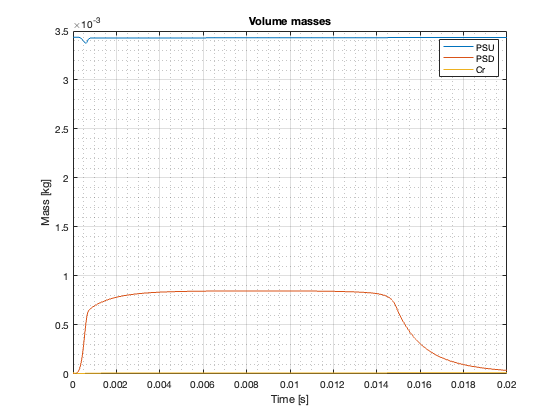

figure(7)
plot(t,m_psu,t,m_psd,t,m_cr)
grid on, grid minor, xlabel('Time [s]'), ylabel('Mass [kg]'), title('Volume masses')
legend('PSU', 'PSD', 'Cr')

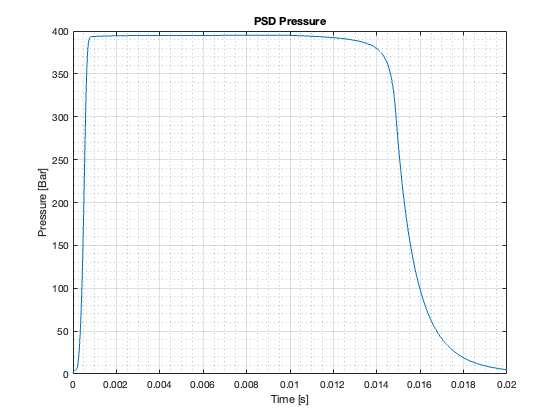

figure(8)
plot(t,P_psd)
grid on, grid minor, xlabel('Time [s]'), ylabel('Pressure [Bar]'), title('PSD Pressure')

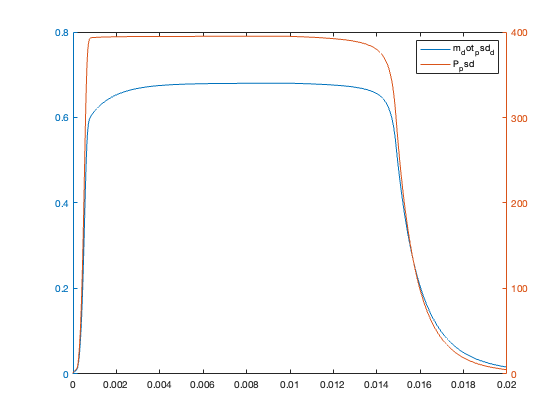

figure(9)
plotyy(t,m_dot_psd_d,t,P_psd),legend('m_dot_psd_d','P_psd')

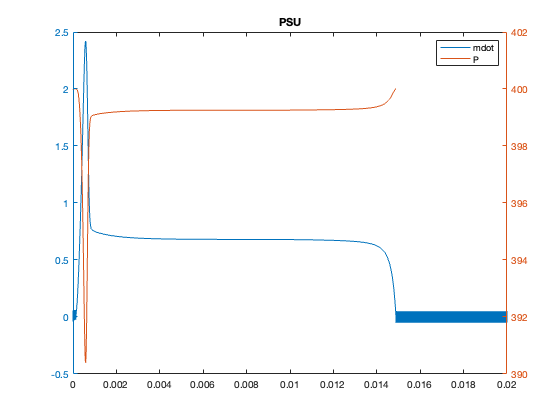

figure(10)
plotyy(t,m_dot_u_psu,t,P_psu),legend('m_dot_psd_d','P_psd'),title('PSU'),legend('mdot','P')

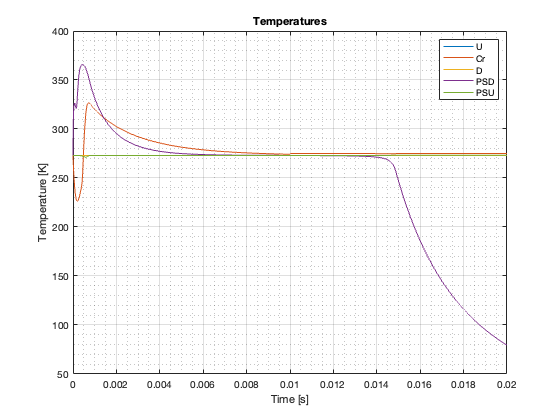

figure(11)
plot(t,T_u,t,T_cr,t,T_d,t,T_psd,t,T_psu)
grid on, grid minor, xlabel('Time [s]'), ylabel('Temperature [K]'), title('Temperatures')
legend('U','Cr','D','PSD','PSU')